# Taller X

### 23/05/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 8 y 9*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

*Notas frente al uso de los métodos:*

#### *        Métodos de integración*

*Los métodos de integración son muy variados, por lo cual, los métodos con los que contamos nos pueden quedar cortos para las necesidades que tenemos y sea necesario un nuevo método para la resolución de ejercicios.*

`        [quad, raices, nodos, coefs] = GaussLegendre( f, a, b, N), `*Cuadratura de Gauss-Legendre*

`            - f funcion integrando creada con @`

`            - a y b limites superior e inferior de integracion`

`            - N es el numero de nodos en la cuadratura`

`            - quad es el valor de cuadratura`

`            - raices es el vector de raices del polinomio de Legendre N`

`            - nodos es el vector de nodos de la cuadratura en [a,b]`

`            - coefs es el vector de pesos de la cuadratura`

`        El error para este metodo se calcula como se indica:`

            `- Aquí el error toma la forma diferencial:`

`        ((b - a)/ 2)^(2*N + 1) * ( 2^(N + 1) * factorial(N)^4 ) / ((2*N +1) * factorial(2*N)^3)* max{f^(2*N)(x)}`

            `- El error tiene orden O( ((b - a)/(N - 1)) ), con exponente N + 1 con N par y N + 2 con N impar, N es el número de puntos. En las clases se explica con M tal de que M + 1 es el número de puntos, así las formulas quedarían M + 2, y M + 3 respectivamente.`

***Reglas abiertas:***

*No contamos con métodos de integraciones abiertas especificamente, por lo cual si se busca implementar el método, es necesario definir.*

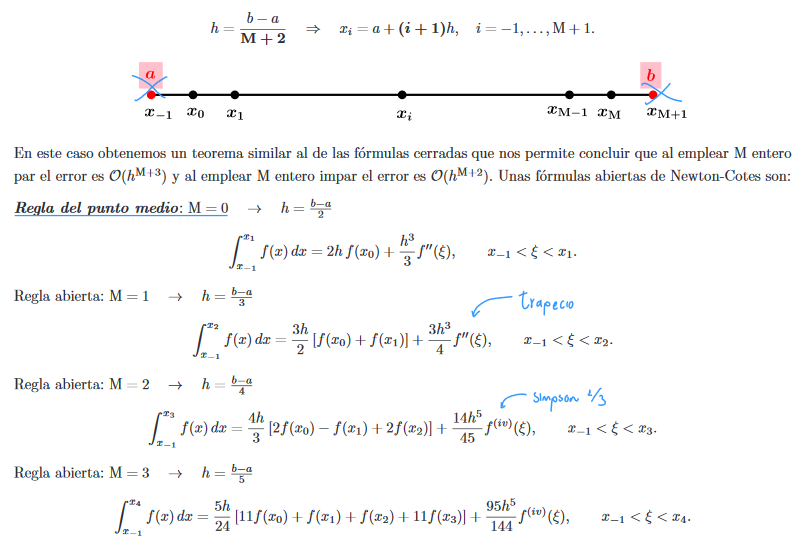

***Reglas cerradas:***

*Contamos con algunos métodos de integración cerrada, pero igualmente, de ser necesario, algunos otros necesitan ser creados, de igual forma estos métodos cuentan con una forma simple, la cual toma el mínimo número de intervalos posibles para efectuar el método.*

`        s = simprl (f, a, b, M)`*, Método de Simpson*

`            - f funcion integrando creada con @`

`            - a y b son los limites superior e inferior de integracion`

`            - M es el numero de subintervalos`

`            - s es la suma de la regla de simpson`

`        El error para este metodo se calcula como se indica:`

            `- Condición simple: ``- h^5 / 90 * max{f^(iv)(x)} : h = (b - a)/2`

            `- Condición compuesta:`` - h^4 / 180 *(b - a) *max{f^(iv)(x)} : h = (b - a)/M`

`        s =  traprl(f, a, b, M)`*, Método de trapecios*

`            - f funcion integrando creada con @`

`            - a y b son los limites superior e inferior de integracion`

`            - M es el numero de subintervalos`

`            - s es la suma de la regla trapezoidal (integral)`

`        El error para este metodo se calcula como se indica:`

            `- Condición simple: - ``h^3 / 12 * max{f''(x)} : h = (b - a)/2`

            `- Condición compuesta:`` - h^2 / 12 *(b - a) *max{f''(x)} : h = (b - a)/M`

*        >>Durante los talleres se agrega el método de punto medio, con el cual el error se halla como:*

`        s = midpntrl (f, a, b, M)`*, Método de punto medio*

`            - f funcion integrando creada con @`

`            - a y b son los limites superior e inferior de integracion`

`            - M es el numero de subintervalos`

`            - s es la suma de la regla de punto medio`

`        El error para este metodo se calcula como se indica:`

            `- Condición simple: ``h^3 / 3 * max{f''(x)} : h = (b - a)/2`

            `- Condición compuesta:`` (b - a) / 6 *h.^2 *max{f''(x)} : h = (b - a)/(M + 2)`

#### *        Métodos de resolución de ecuaciones diferenciales u***nivariable**   

`        E = euler (f, a, b, ya, M)`

`            - f funcion creada con @`

`            - a y b son los extremos izquierdo y derecho`

`            - ya es la condicion inicial  y(a)`

`            - M es el numero de pasos`

`            - E = [T', Y'] donde T es el vector de abscisas y`

`                Y es el vector de ordenadas`

`        T4 = taylor (df, a, b, ya, M) `*Método de Taylor de Orden 4.*

`            - df = [y', y'', y''', y''''] funcion creada con @ donde  y' = f(t, y)`

`            - a y b son los extremos izquierdo y derecho`

`            - ya es la condicion inicial  y(a)`

`            - M es el numero de pasos`

`            - T4 = [T', Y'] donde  T  es el vector de abscisas y`

`                Y  es el vector de ordenadas`

`        H = heun (f, a, b, ya, M)`

`            - f funcion creada con @`

`            - a y b son los extremos izquierdo y derecho`

`            - ya es la condicion inicial  y(a)`

`            - M es el numero de pasos`

`            - H = [T', Y'] donde  T  es el vector de abscisas y`

`                Y es el vector de ordenadas`

`        EM = eulerMod (f, a, b, ya, M)`

`            - f funcion creada con @`

`            - a y b son los extremos izquierdo y derecho`

`            - ya es la condicion inicial  y(a)`

`            - M es el numero de pasos`

`            - EM = [T', Y'] donde  T  es el vector de abscisas y`

`                Y es el vector de ordenadas`

`        R = rk4 (f, a, b, ya, M)`

                        `- f funcion creada con @`

                        `- a y b son los extremos izquierdo y derecho`

                        `- ya es la condicion inicial  y(a)`

                        `- M es el numero de pasos`

                        `- R = [T', Y'] donde  T  es el vector de abscisas`

                        `    y  Y  es el vector de ordenadas`

#### Integración Númerica

Para el taller de esta semana se solucionan dos de las seis integrales presentes, y dos de los cuatro ejercicios en $9\;y\;10$ del taller 9, se propone el uso de los métodos integrales y las propias herramientas de Matlab

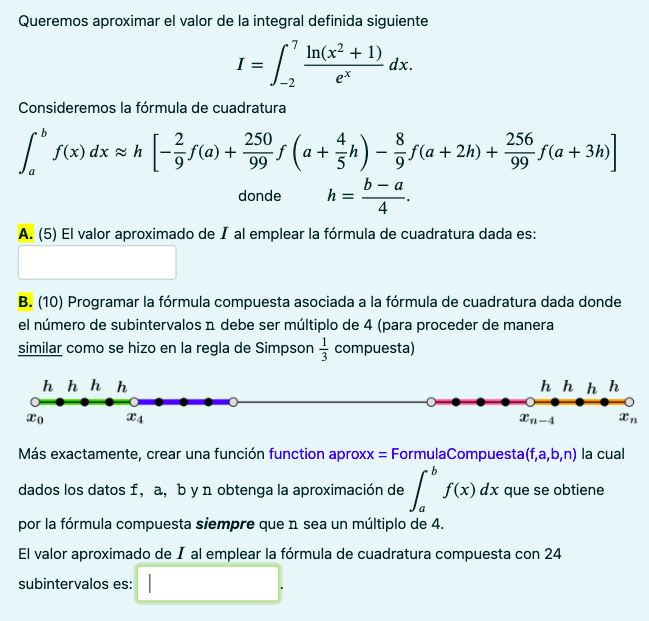

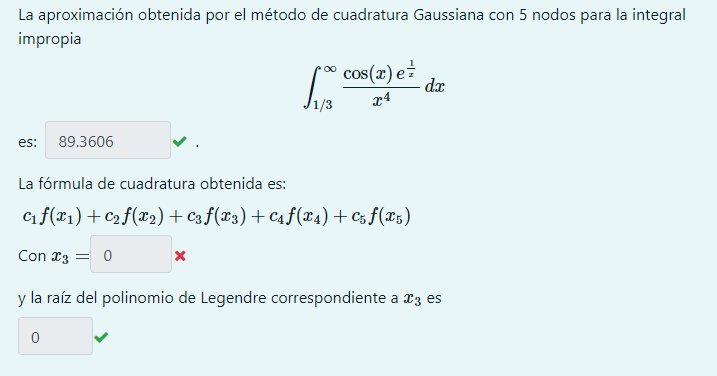

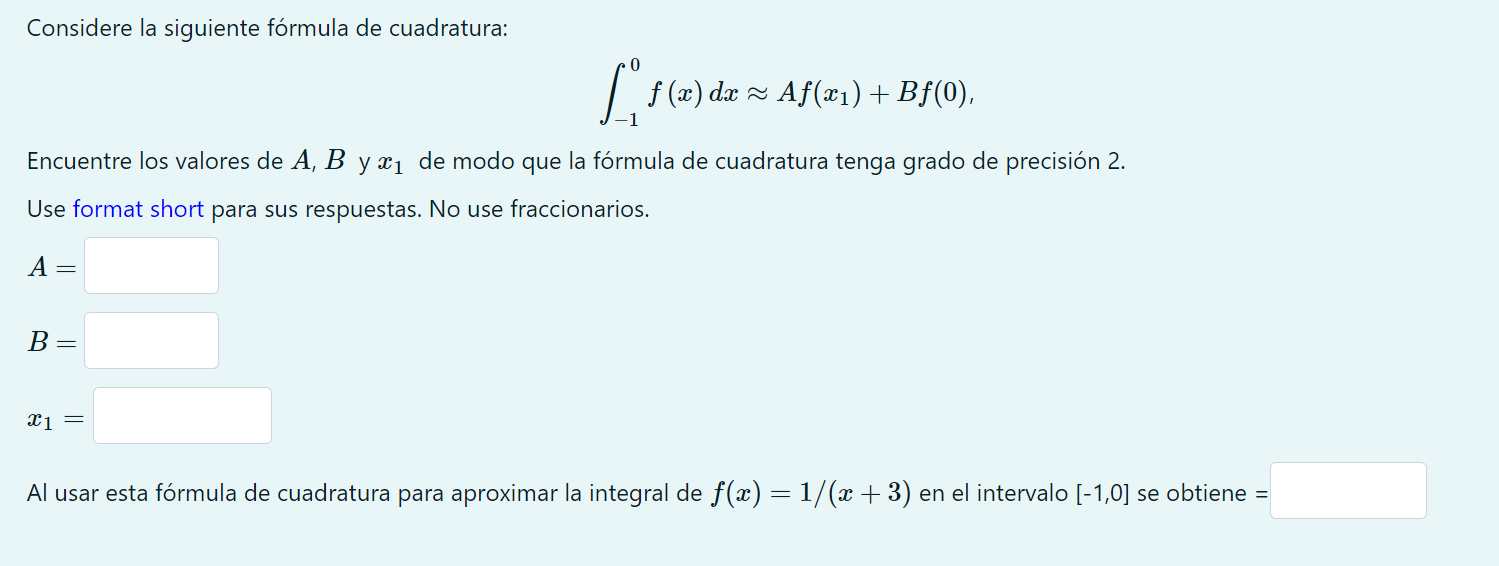

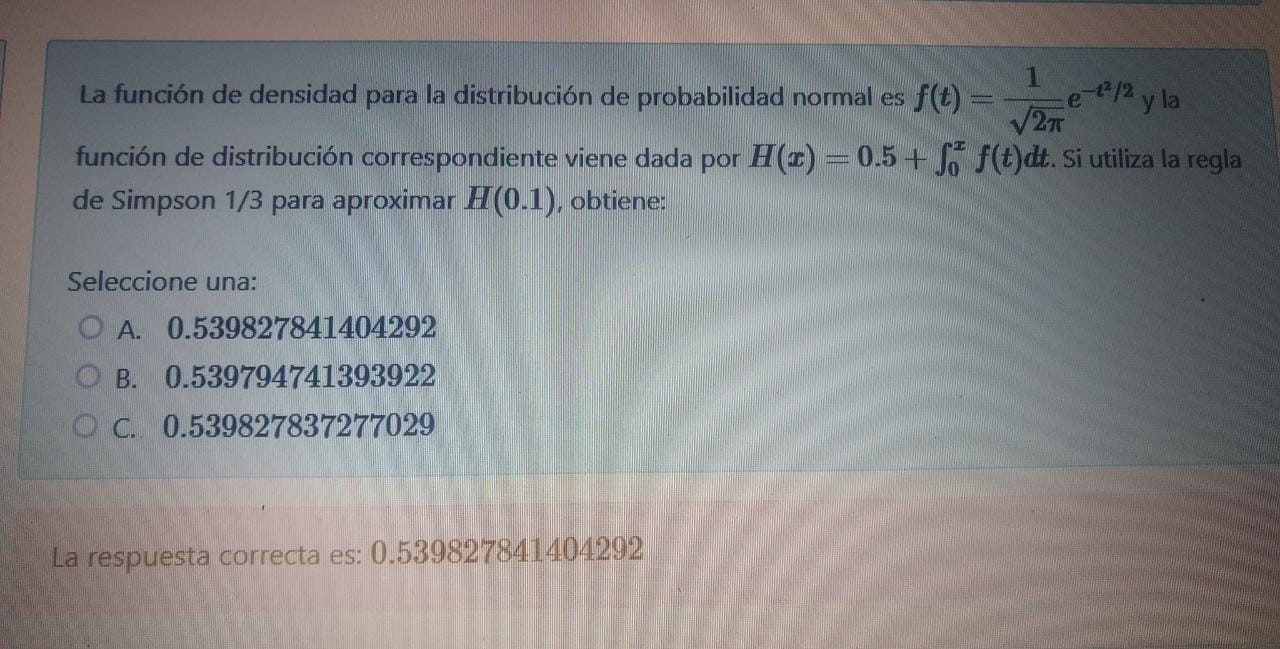

### Solución númerica de ecuaciones diferenciales ordinarias

Para el taller de esta semana se solucionan dos ejercicios: $\left.\left.2\ldotp b\right)\;y\;c\right),y\;3\ldotp$